# Genetic Algorithim in Tandem with pattern search for a PID controller

%0 initialisation and set up
    %0.0 plant transfer function     
        s = tf('s');
        G = (2*s+1)/(5*s^3+5*s+2);
    %0.1 desired cahracteristics
        rise_time=1

rise_time = 1

        settling_time=3

settling_time = 3

        peak_overshoot=20   %in percent copared tosteady state value

peak_overshoot = 20

        undershoot=10       %in percet compared to steady state value

undershoot = 10

    %0.2 Algorithim paramaters
        tolerance=1 %does nothing 

tolerance = 1

        weighting_exponent=[1,1,1]      %rise time,settling time, peak overshoot %,

weighting_exponent =      1     1     1


        weighting_proportional=[1,1,1]  %rise time,settling time, peak overshoot %

weighting_proportional =      1     1     1


        weighting=[weighting_proportional;weighting_exponent]

weighting =      1     1     1
     1     1     1


        %if solution is weird then modify mutation factor and other options
        max_generations=18;
        population_size=30;
        elite_proportion=0.05;
        crossover_fraction=0.75;    %%exploitative
        mutation_factor=0.18;       %%eplorative
        num_tests=5               %no. times to run the algorithim 

num_tests = 5

        x_bound=1                %acceptable solution to stop re running more than sum of weighting is reasonable

x_bound = 1

        
        % options on the algorithim 
        options=optimoptions(@ga,"MaxGenerations",max_generations,'PopulationSize',population_size,'SelectionFcn',{@selectiontournament,4},'EliteCount',ceil(elite_proportion*population_size),'CrossoverFraction',crossover_fraction,'CrossoverFcn',@crossoverheuristic,'MutationFcn',{@mutationadaptfeasible,mutation_factor});
        x=inf;

%1 algorithim implementation 
    for i=1:num_tests    %for the number of tests
        
        %1.1 execute combined algoritthim
            [K_test,x_test]=PID_Best(G,rise_time,settling_time,peak_overshoot,undershoot,options,tolerance,weighting);
        %1.2 if new test is better than old overwrite data
            if x_test<x
                K=K_test;
                x=x_test;
            end
        %1.3 if the new test is sufficiently good stop re running
            if x<x_bound
                number_of_iterations=i
                break
            end
    end

Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.
Optimization terminated: maximum number of generations exceeded.
Optimization terminated: mesh size less than options.MeshTolerance.



%2 testing output solution 
    %2.1 defining solution 
        C=K(1)+K(2)/s+K(3)*s    %controller transfer function 

C =
 
  5.765 s^2 + 1.396 s + 2.318
  ---------------------------
               s
 
Continuous-time transfer function.



        H=feedback(C*G,1)       %closed loop transfer function 

H =
 
      11.53 s^3 + 8.557 s^2 + 6.032 s + 2.318
  -----------------------------------------------
  5 s^4 + 11.53 s^3 + 13.56 s^2 + 8.032 s + 2.318
 
Continuous-time transfer function.



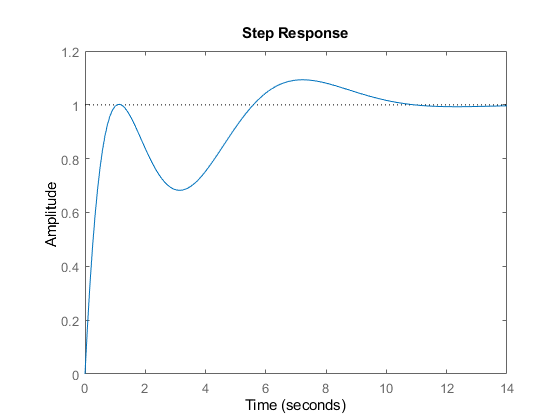

    %2.2 simulation solution 
        step(H)                 %step response

        stepinfo(H)             %step paramaters

ans = struct with fields:
        RiseTime: 0.6455
    SettlingTime: 9.8619
     SettlingMin: 0.6824
     SettlingMax: 1.0931
       Overshoot: 9.3085
      Undershoot: 0
            Peak: 1.0931
        PeakTime: 7.2225


    %2.3 final fitness value
        fitness=pidtest(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,K)

fitness = 310.0341

function [K,x]=PID_Best(G,rise_time,settling_time,peak_overshoot,undershoot,options,tolerance,weighting)

fitness_function=@(K)pidtest(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,K);

[K,~] = ga(fitness_function,3,-1*eye(3),zeros(3,1),[],[],[],[],[],[],options);

[K,x] = patternsearch(fitness_function,K,-1*eye(3),-1e-6*ones(3,1));

end

function fitness=pidtest(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,K)
    s=tf('s');
    if ~all(K)
        fitness=inf;
    else
        C=K(1)+K(2)/s+K(3)*s;
        H=feedback(C*G,1);
        [Y,T]=step(H,[0:settling_time/1000:4*settling_time]);
        fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot/100,weighting);
        
        if isnan(fitness)
            fitness=inf;
        end
    end
    
end
        
    function fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,weighting)
        fitness=0;
        for i=1:length(Y)
            y=Y(i);
            t=T(i);
            fitness=fitness+get_fitness(y,t,rise_time,settling_time,peak_overshoot,weighting);
        end
    end
    
    
    function fitness=get_fitness(y,t,rise_time,settling_time,peak_overshoot,weighting)
    fitness=0;
        if t<rise_time
            if (y-1)>peak_overshoot/100
                fitness=weighting(1,3)*(y-peak_overshoot/100)^weighting(2,3);
            end
        
        elseif t<settling_time
            
            if (y-1)>peak_overshoot/100
                fitness=weighting(1,3)*(y-peak_overshoot/100)^weighting(2,3);
            elseif y<0.9
                fitness=weighting(1,1)*(0.9-y)^weighting(2,1);
            end
        
        else
            fitness=weighting(2,1)*abs(1-y)^weighting(2,2);
            
        end    
    end